close all;
clear all;
clc;

% Primary coil inductance
L_pri_measured = 8e-6; % H

% MMC Bank Capacitance
C_MMC_measured = 0.045e-6; % F

VAC_in = 60;                % VAC (Vrms)
V_in_pk = sqrt(2)*VAC_in;   % Vpk (V)
Vbus_rail = 2*V_in_pk       % Bus rail voltage (VDC)

Vbus_rail = 169.7056


f_res = 264e3;              % Resonant frequency Hz
t_on = 13e-6;               % On time, (sec)

% Characterisic Impedance (Ohm)
Z_pri = sqrt(L_pri_measured/C_MMC_measured)

Z_pri = 13.3333


%omega = 2*pi*f_res
%I_pri_pk = (Vbus/Z_pri)*sin(omega*t_on) % Not accurate

N_cycles = t_on/(1/f_res)

N_cycles = 3.4320

% Full-bridge design, therefore Vbus_rail - (-Vbus_rail) = 2*Vbus_rail
% across the primary tank
I_pk = (2.0*Vbus_rail/Z_pri) * N_cycles;

I_pk_est = I_pk * 2 % Closer to LTspice simulation

I_pk_est = 174.7289

## MATLAB Estimate: 224 A, LTSpice: 218 A

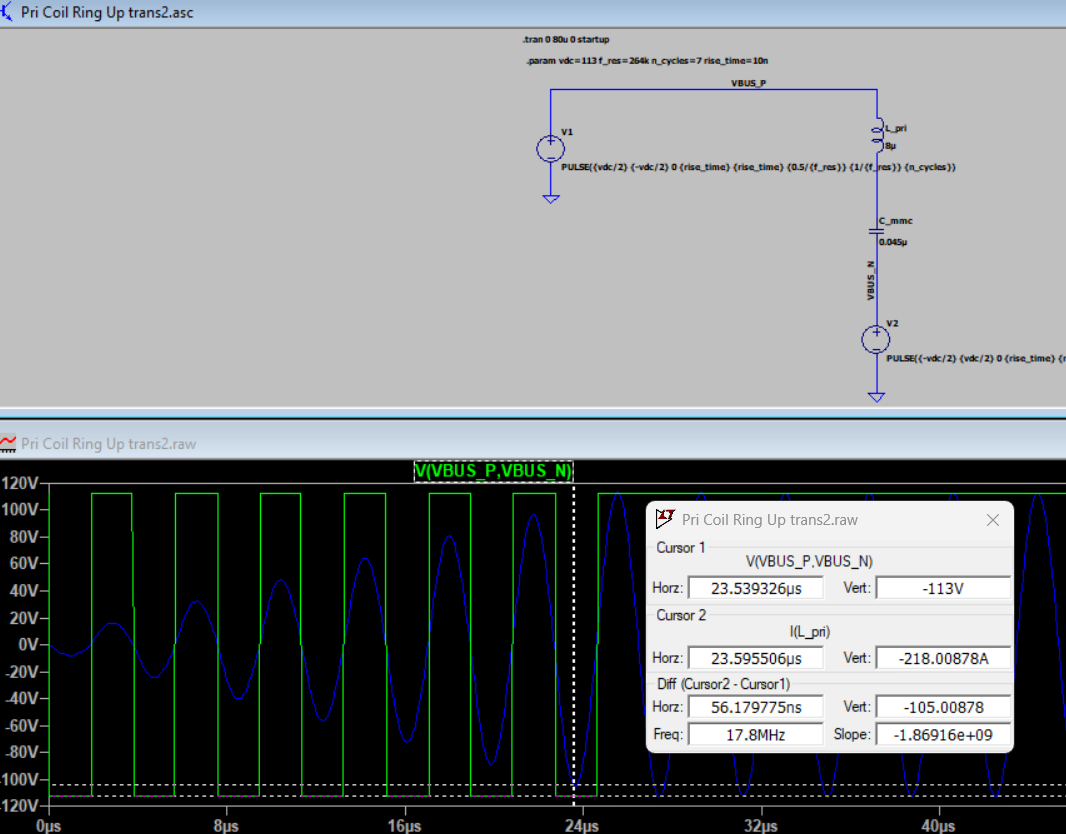

## MATLAB Estimate: 176 A, LTSpice: 174 A